# Analyze Pretrained Network Using Deep Network Designer

This example shows how to visualize a network for transfer learning using the Deep Network Designer app.

Transfer learning is the process of taking a pretrained deep learning network and fine-tuning it to learn a new task. Using transfer learning is usually faster and easier than training a network from scratch. You can quickly transfer learned features to a new task using a smaller amount of data.

## **Prepare Network**

This network is the same as what we used for the previous exercise. 

load('netInPredict.mat'); 
deepNetworkDesigner(TrainedNetwork); 

Deep Network Designer provides a selection of pretrained image classification networks that have learned rich feature representations suitable for a wide range of images. Transfer learning works best if your images are similar to the images originally used to train the network. If your training images are natural images like those in the ImageNet database, then any of the pretrained networks is suitable.

If your data is very different from the ImageNet data—for example, if you have tiny images, spectrograms, or nonimage data—training a new network might be better. 

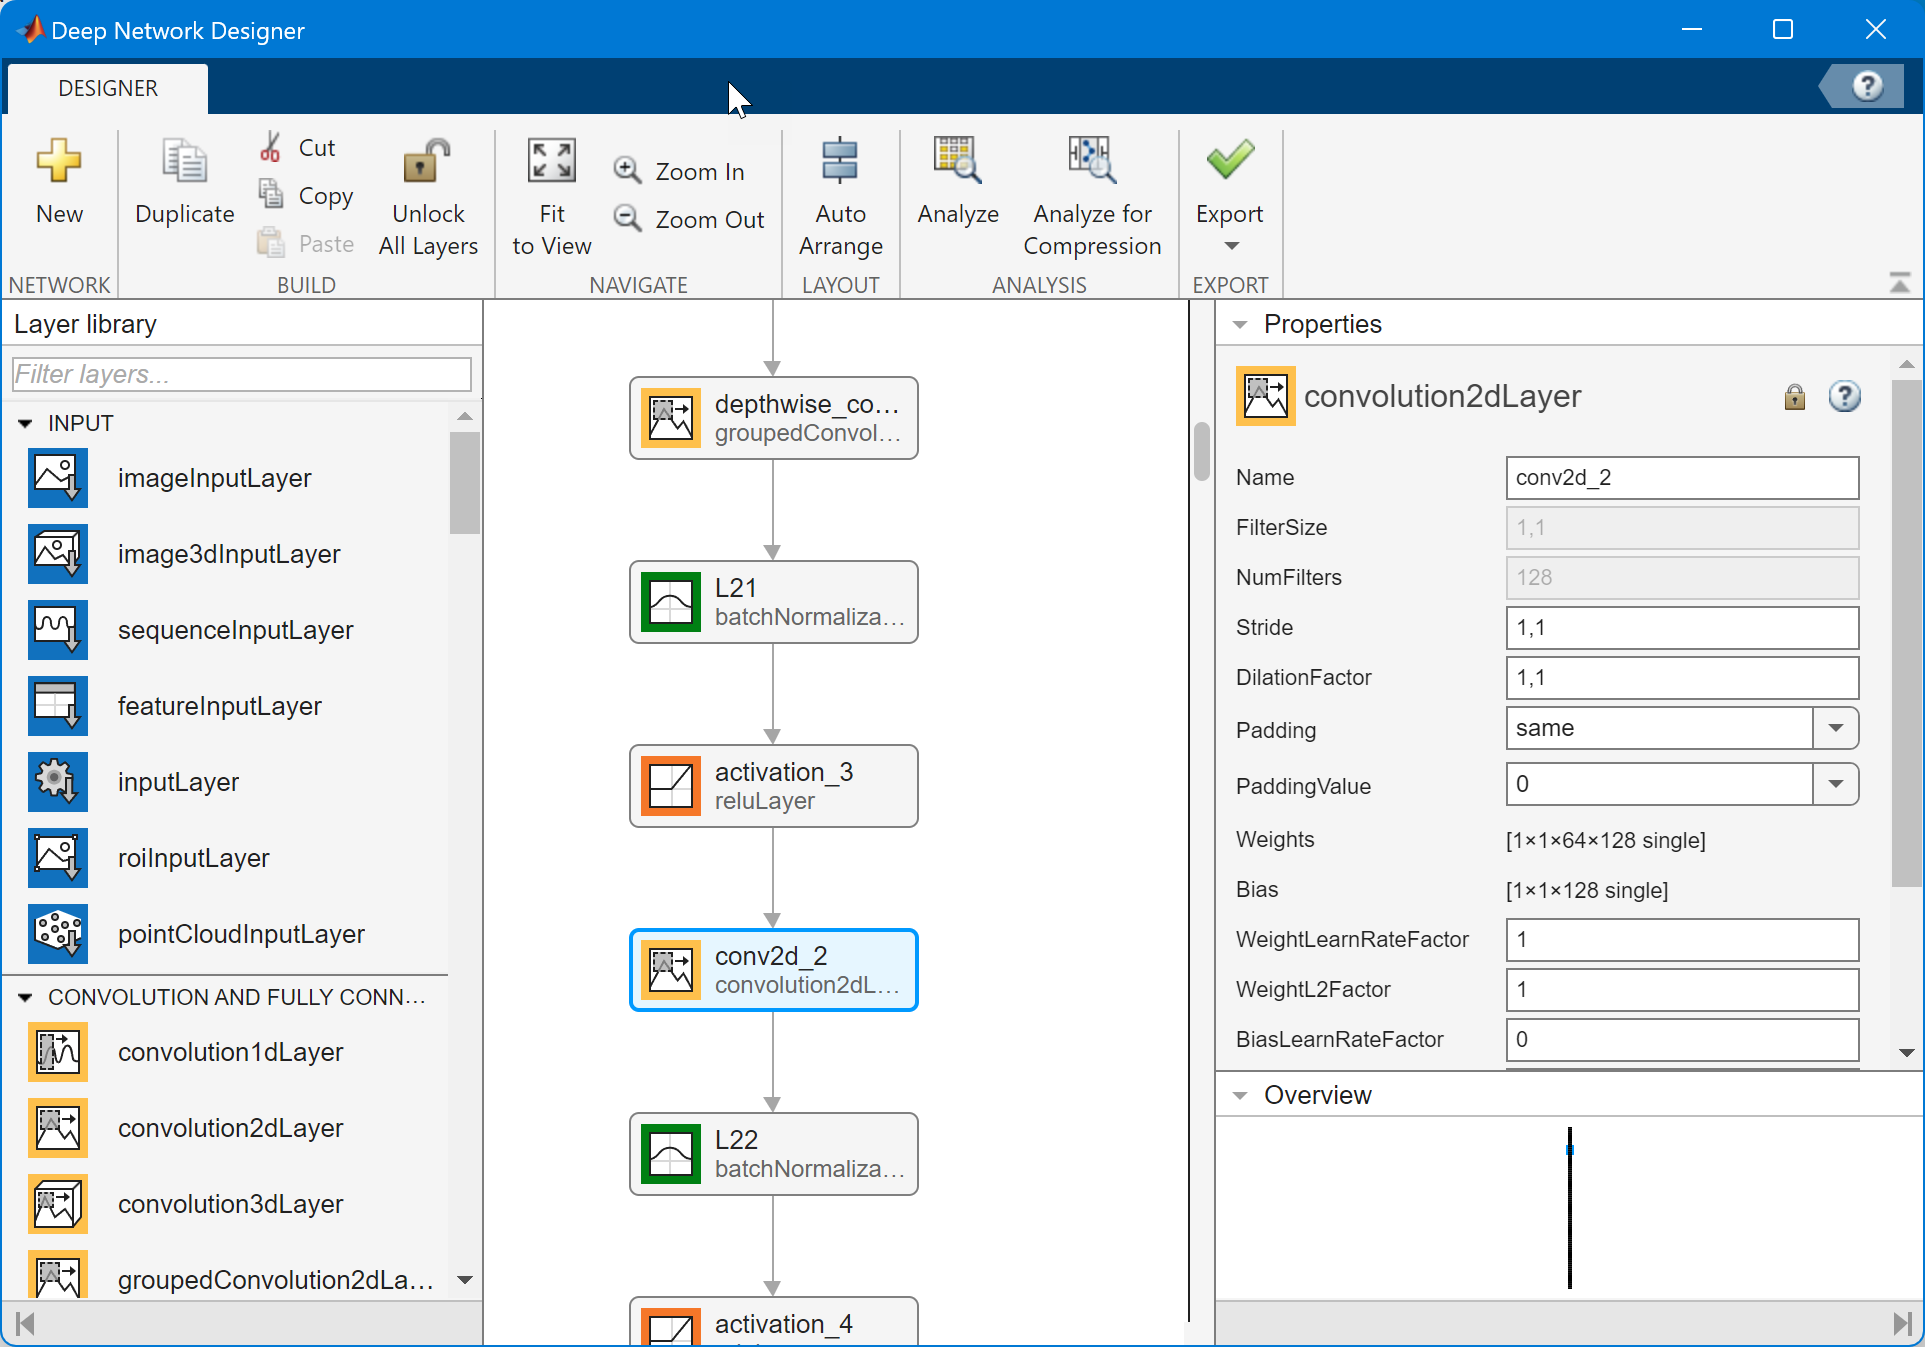

## **Check Network**

To check that the network is ready for training, click **Analyze**. The Deep Learning Network Analyzer reports zero errors or warnings, therefore, the network is ready for next steps. To export the network, click **Export**. The app saves the network in the variable `net_1`.

analyzeNetwork(TrainedNetwork); 


Notice the number of layers and total amount of learnable parameters. 

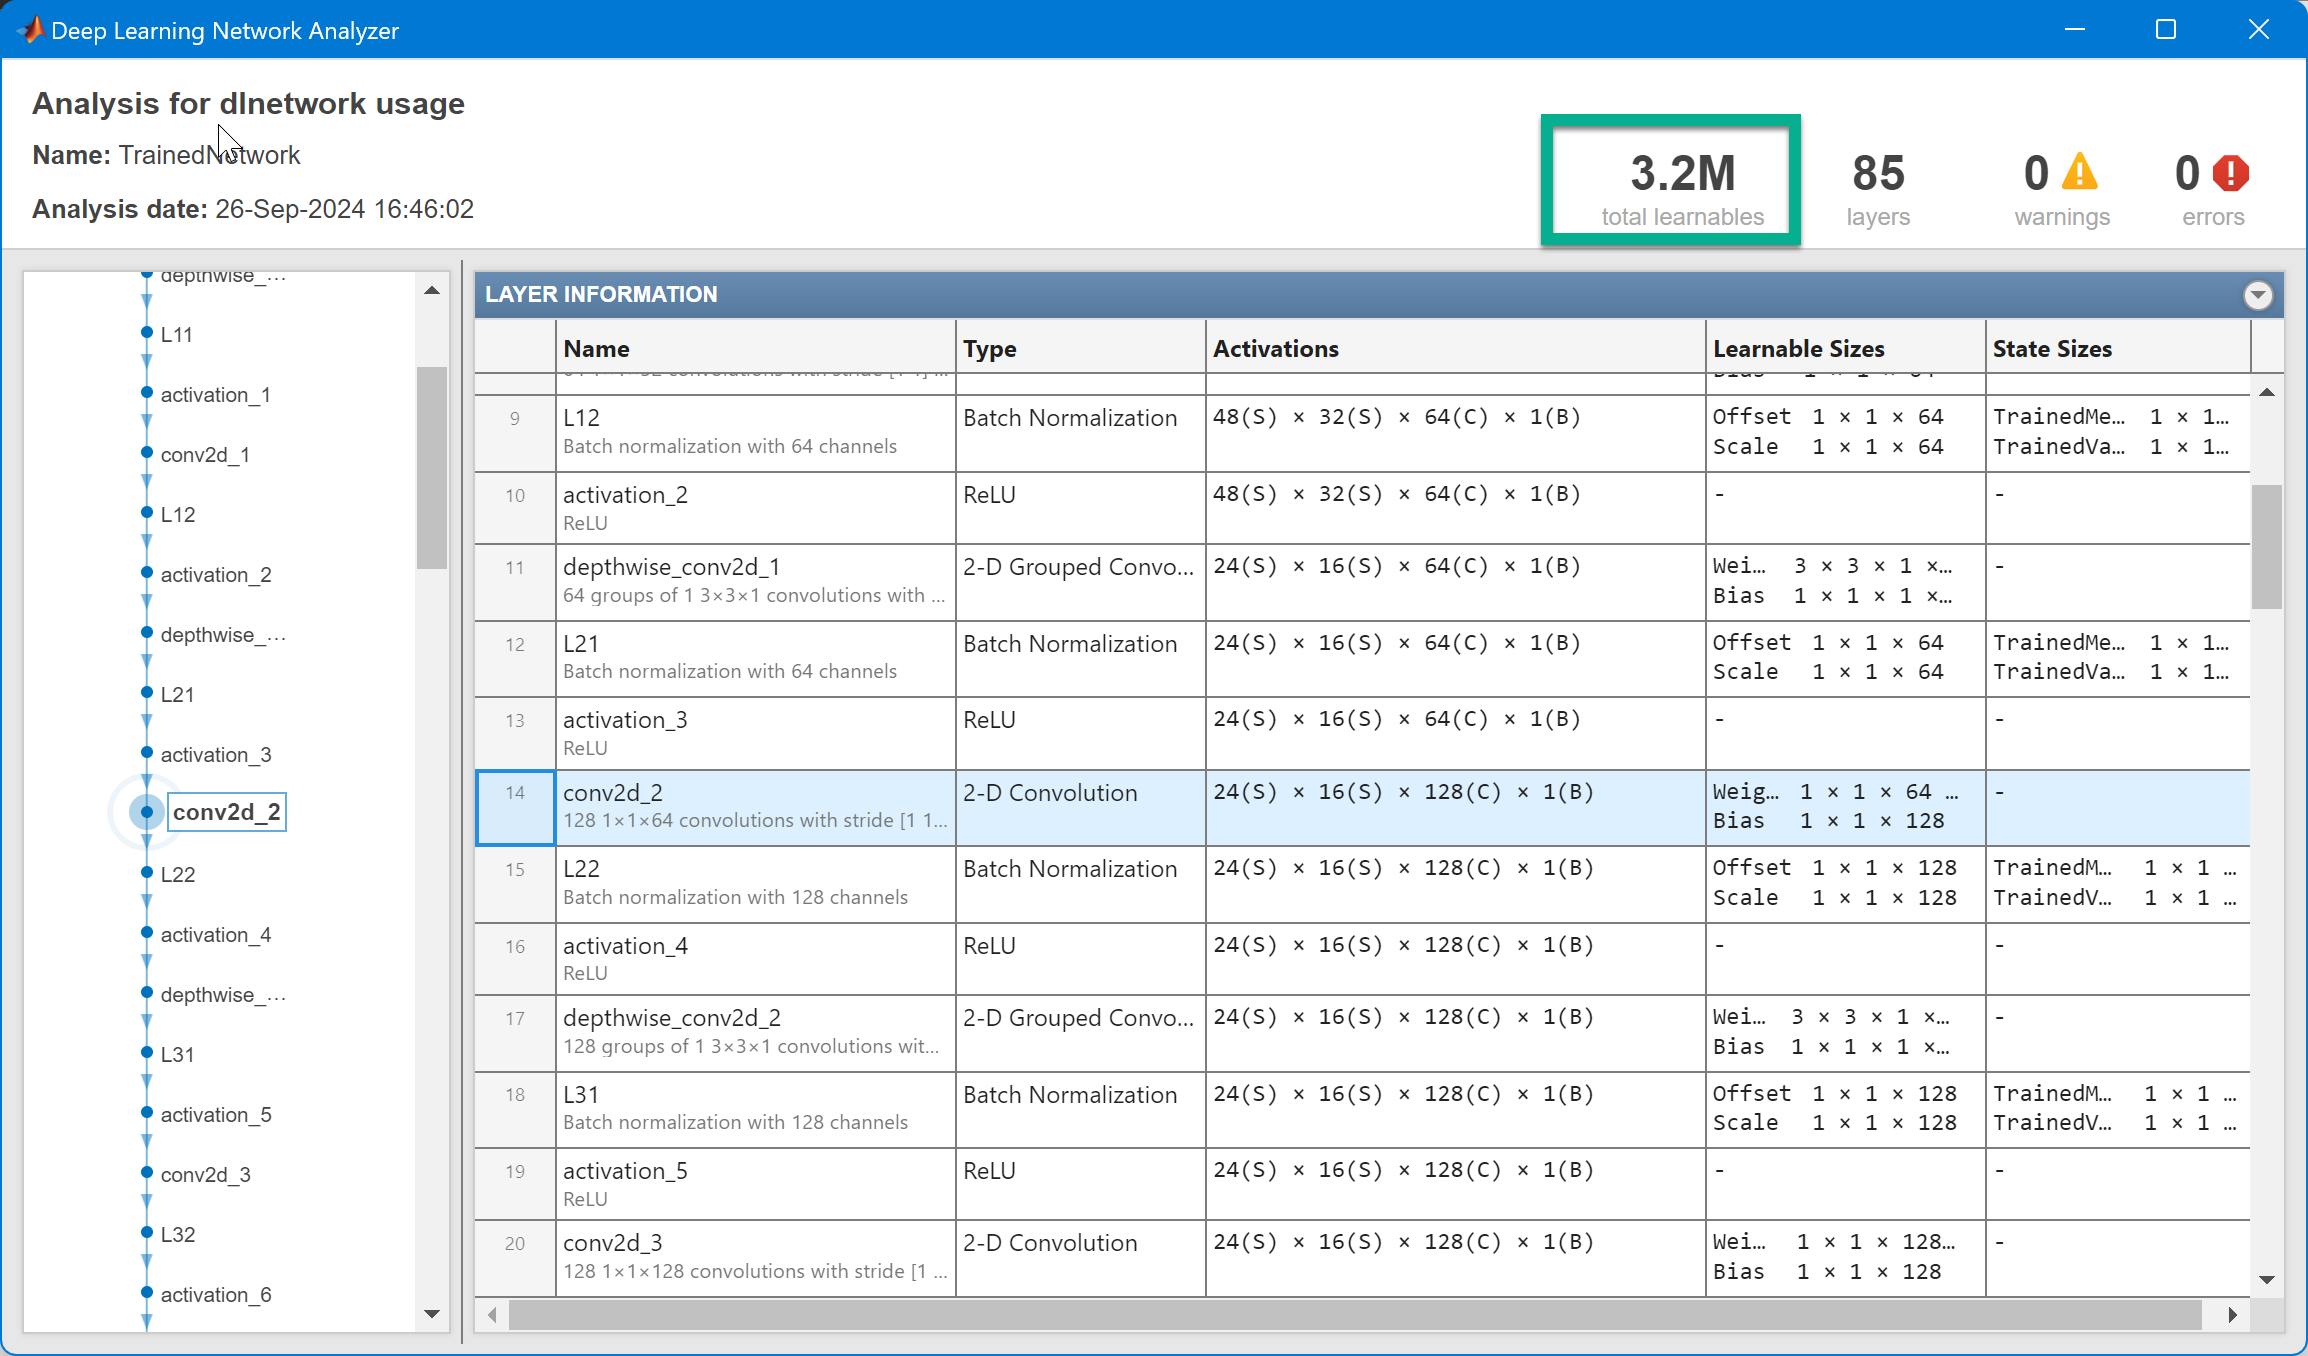

## Potential compression needs

Get a report on how much compression pruning or projection of the network can achieve by clicking the **Analyze for compression** button in the toolstrip.

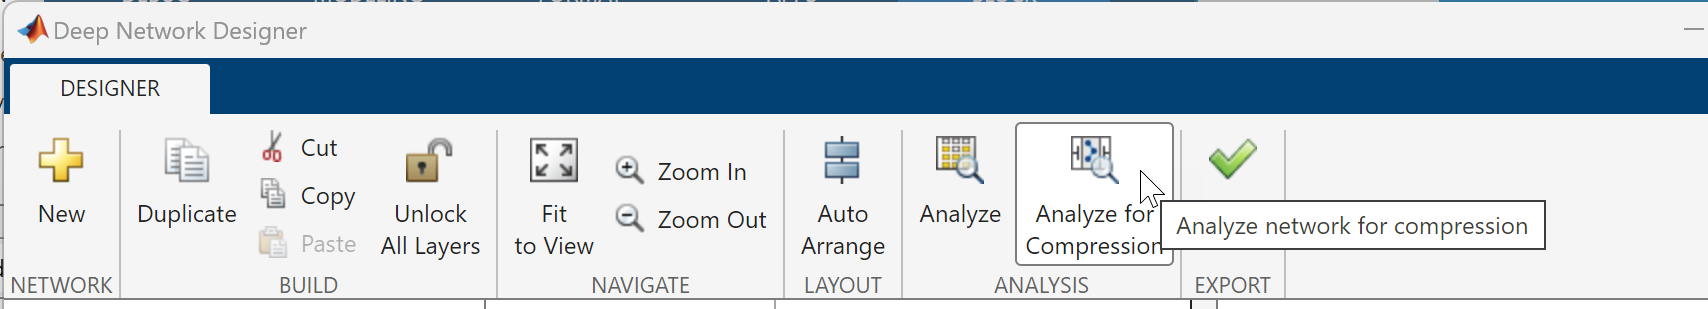

The analysis report shows that you can compress the network using either pruning or projection. You can also use a combination of both techniques. If you use both techniques, the simplest workflow is to first perform pruning and then projection.

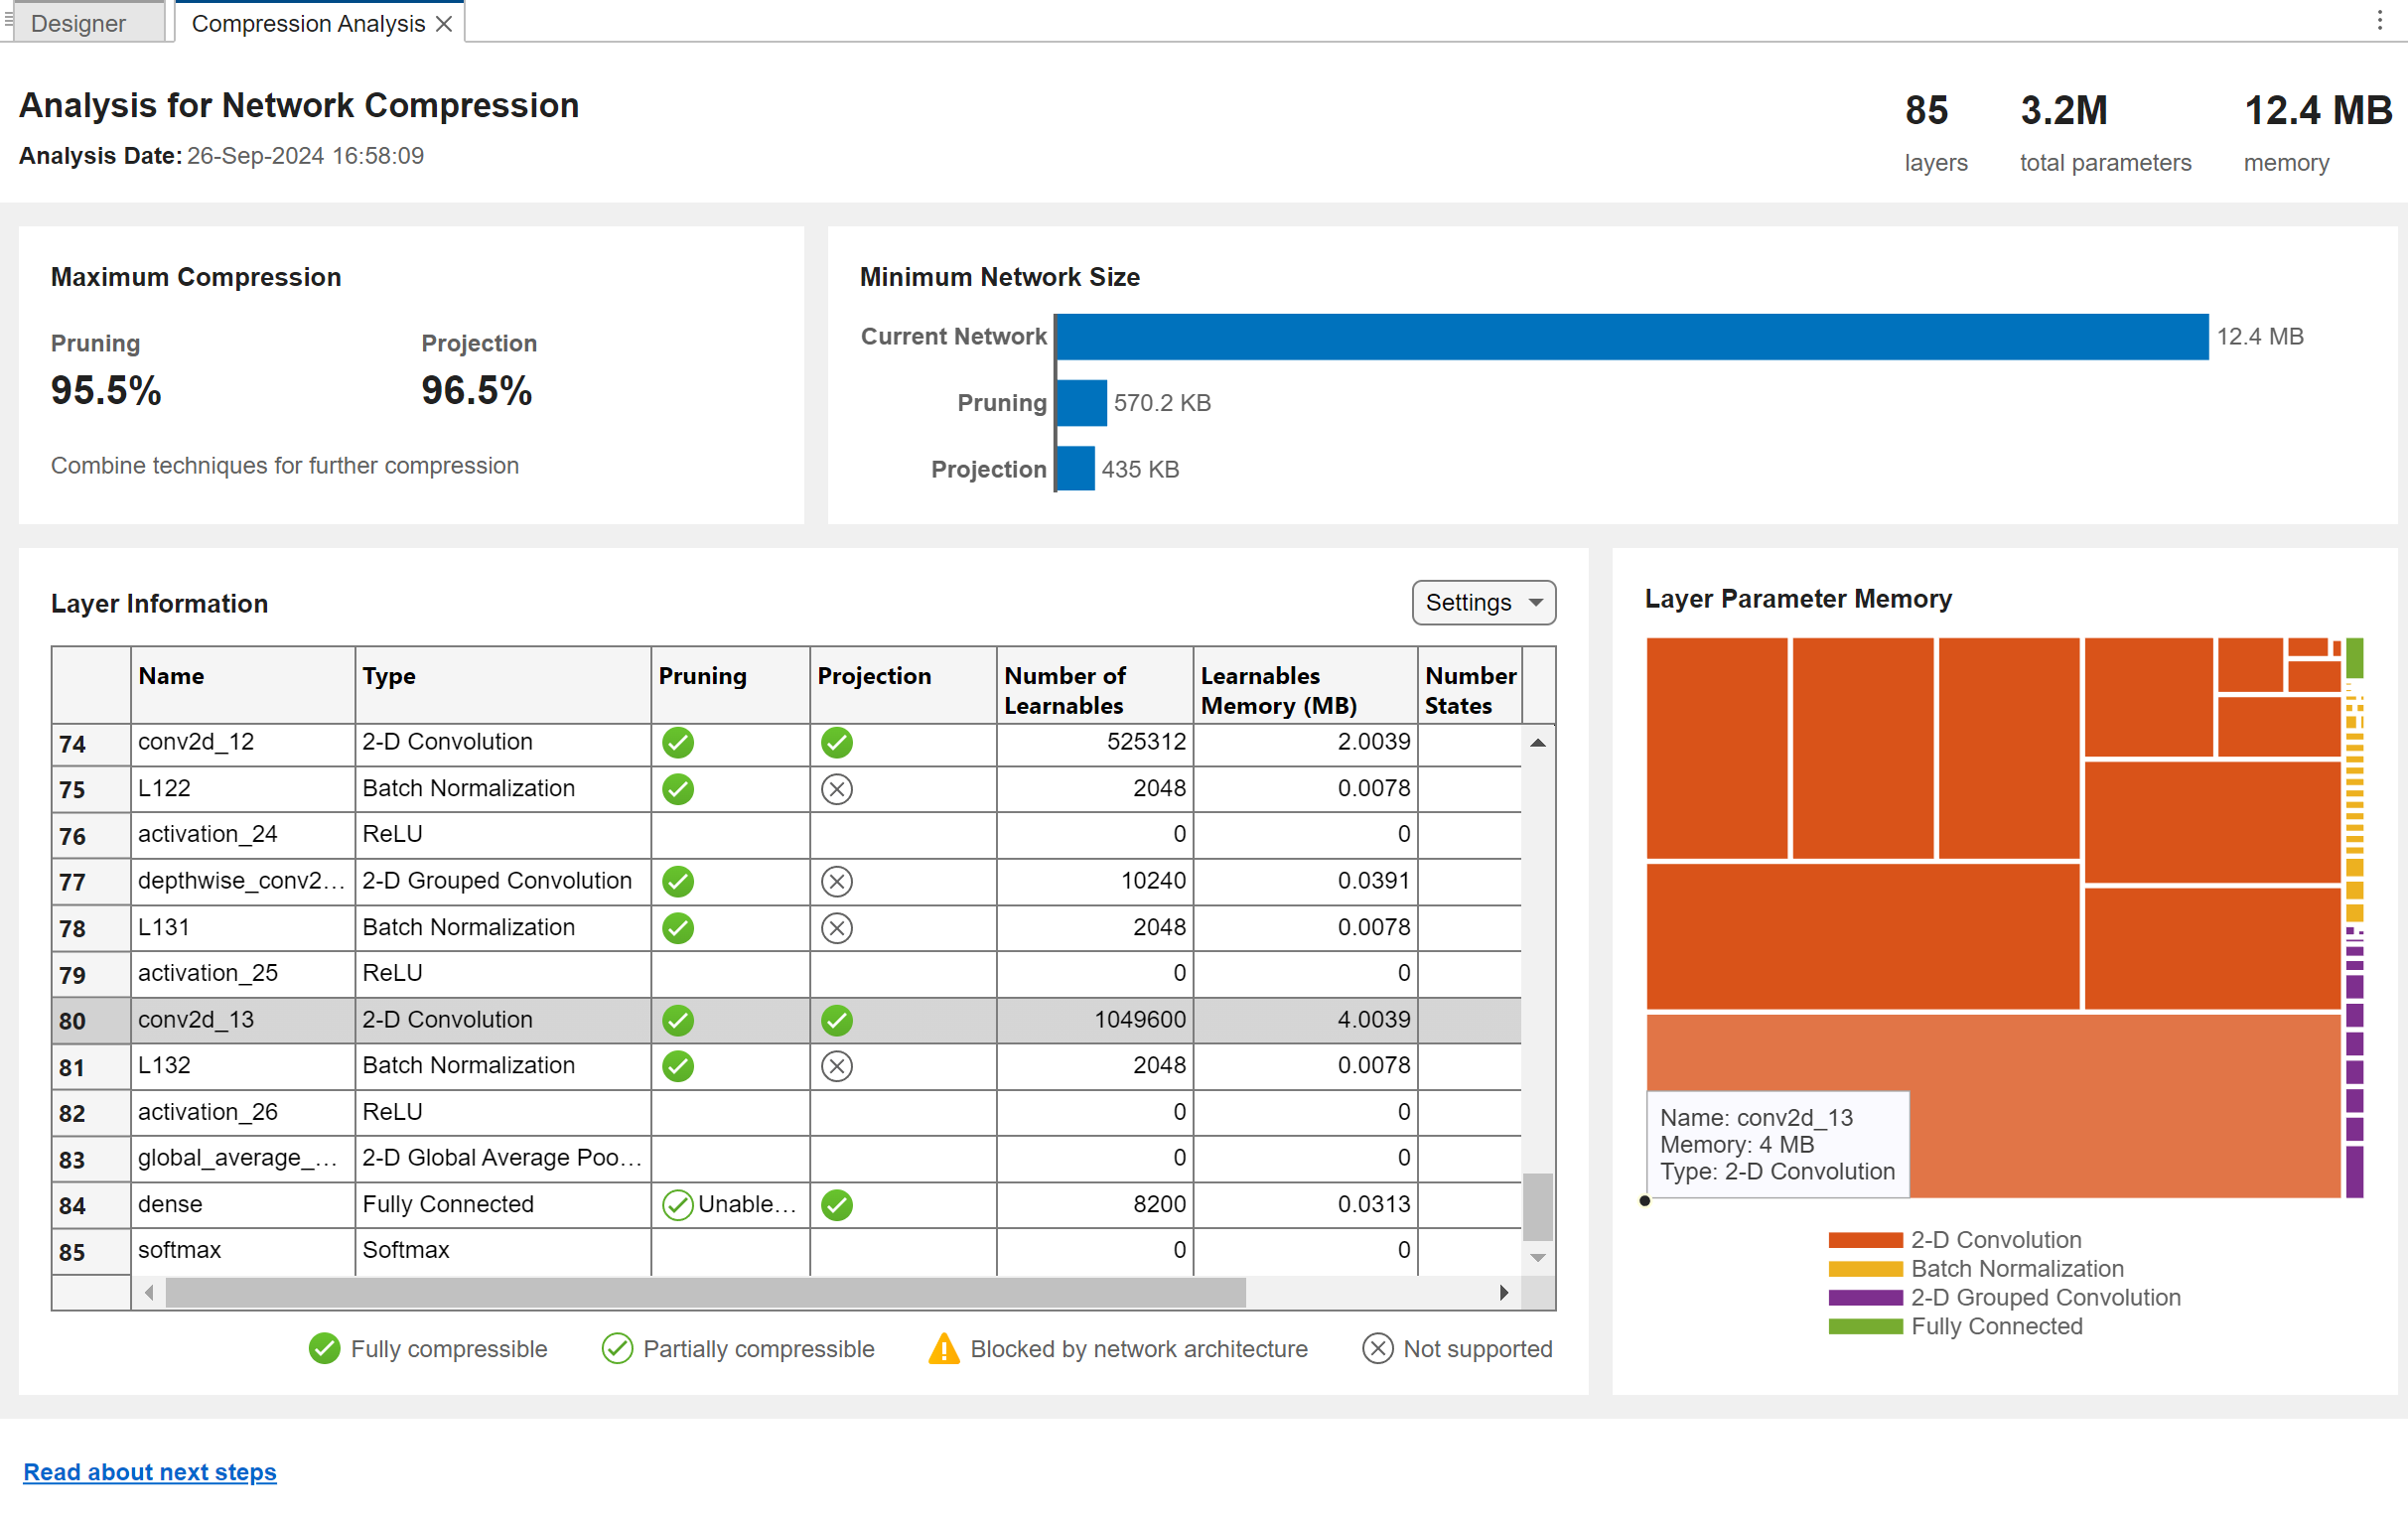

### Reference

[https://www.mathworks.com/help/deeplearning/ug/analyze-and-compress-1d-convolutional-neural-network.html](https://www.mathworks.com/help/deeplearning/ug/analyze-and-compress-1d-convolutional-neural-network.html)